clear all
close all

Построение графика несущей опоры 

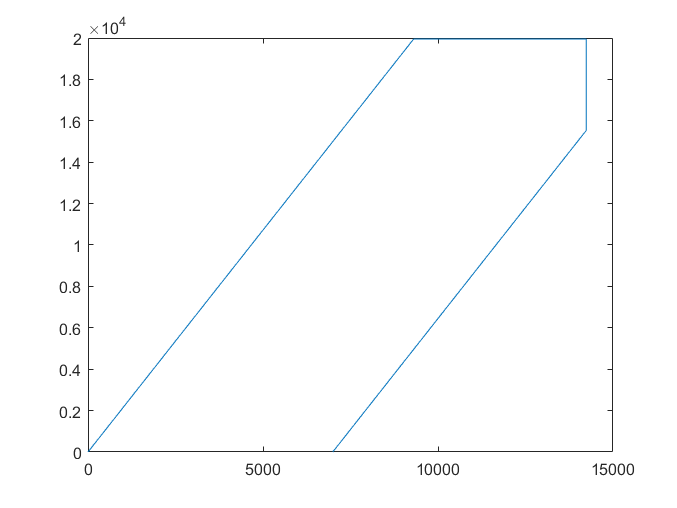

% входные параметры
angle = 65;
l1 = 22017; % длина участка 1
b = 6992;
h = 19991;

% l2 и l3 - вычисляются динамически 

% координаты потосянных точек 

x_point_1 = 0;
y_point_1 = 0;

x_point_2 = l1*cosd(angle);
y_point_2 = l1*sind(angle);

y_point_4 = h - 4457;
x_point_4 = y_point_4/tand(angle) + b;

y_point_3 = y_point_2;
x_point_3 = x_point_4;

x_point_5 = b;
y_point_5 = 0;

X_point = horzcat(x_point_1, x_point_2, x_point_3, x_point_4, x_point_5);
Y_point = horzcat(y_point_1, y_point_2, y_point_3, y_point_4, y_point_5);

plot(X_point, Y_point)

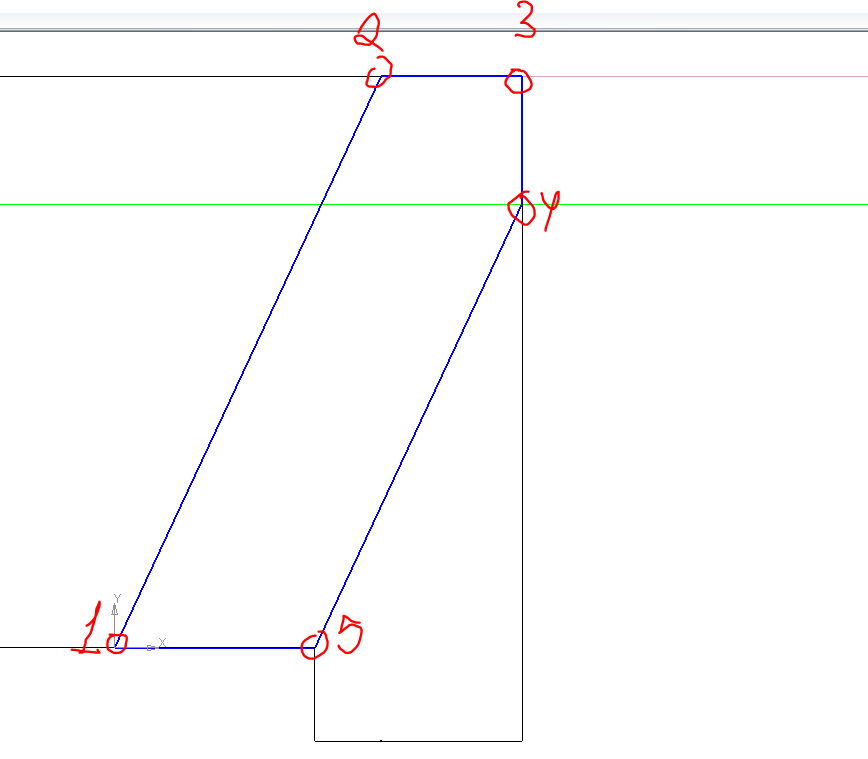

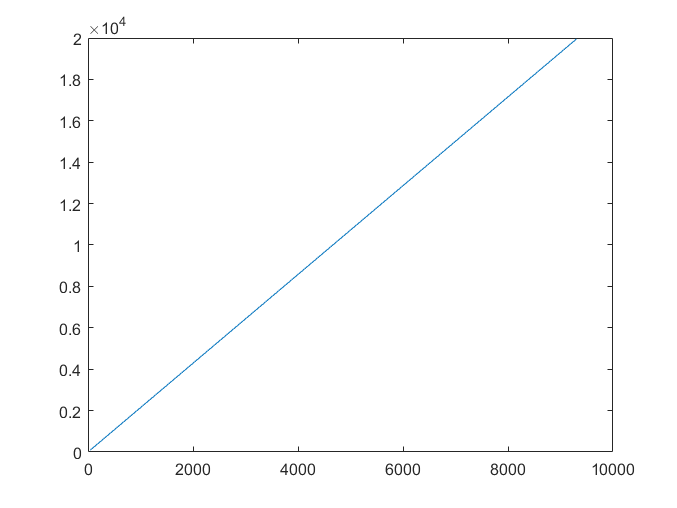

%% УЧАСТОК_1 - наклонный участок

% расчет шага 
l12 = l1;
% N12 = 100; % количество точек не участке 1
% dx_12 = l12/N12;
N12 =  round(l12*0.01,-1);
dx_12 = l12/N12;

% заполнение масивов
for i = 1 : N12
    step12 = dx_12*i;
    x1(i) = cosd(angle)*step12;
    y1(i) = sind(angle)*step12;
end


% график
plot(x1, y1)

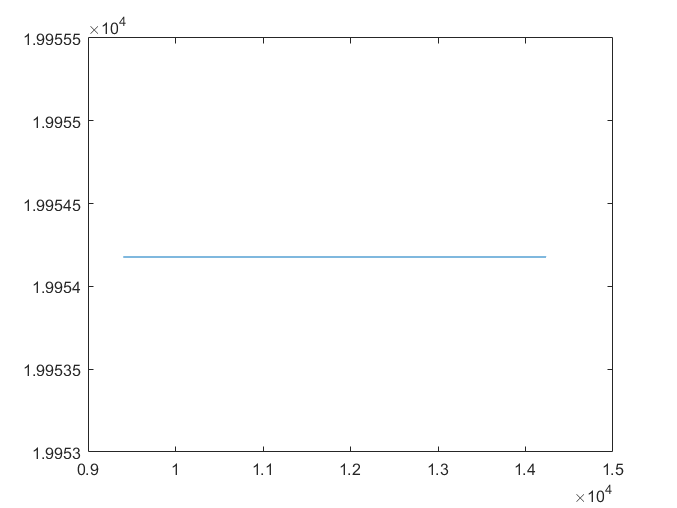

% УЧАСТОК 2 - горизонтальный участок
% координаты начала и конца 


% расчет шага 
l23 = sqrt((x_point_2 - x_point_3)^2 + (y_point_2 - y_point_3)^2);
% N23 = 100;
% dx_23 = l23/N23;
N23 =  round(l23*0.01,-1);
dx_23 = l23/N23;

% заполнение масивов
for i = 1 : N23
    step23 = dx_23*i;
    x2(i) = x_point_2 + step23;
    y2(i) = y_point_2;
end

plot(x2, y2)

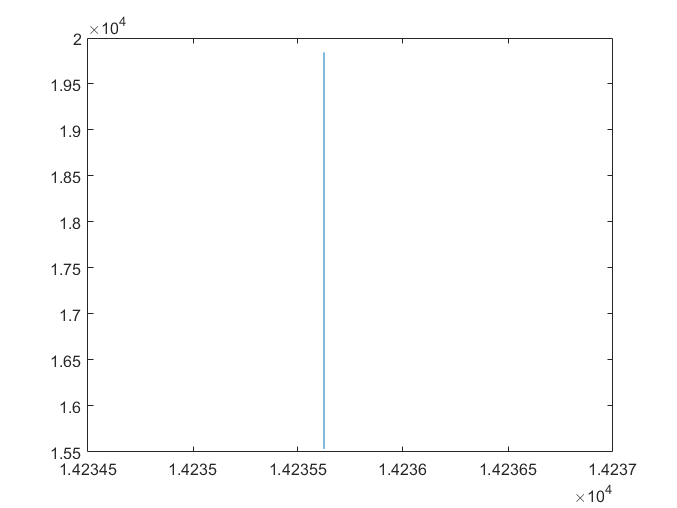

% УЧАСТОК 3 - вниз

% координаты начала и конца


% расчет шага 
l34 = sqrt((x_point_4 - x_point_3)^2 + (y_point_4 - y_point_3)^2);
% N34 = 100;
% dx_34 = l34/N34;
N34 =  round(l34*0.01,-1);
dx_34 = l34/N34;

for i = 1 : N34
    step34 = dx_34*i;
    x3(i) = x_point_3;
    y3(i) = y_point_3 - step34;
end

plot(x3, y3);

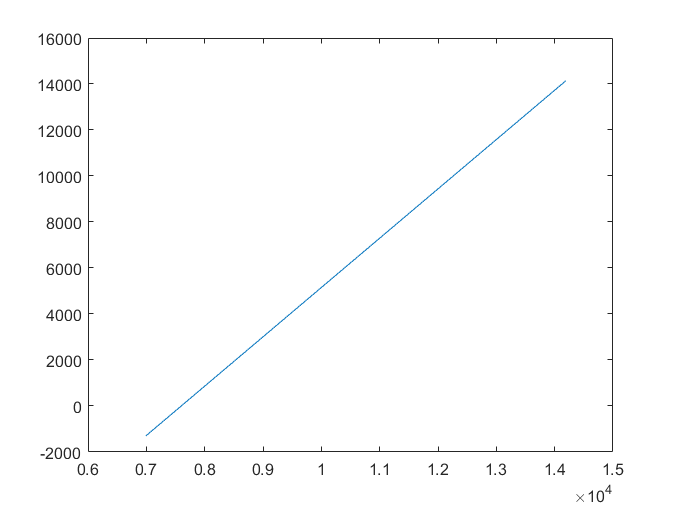

% УЧАСТОК 4 - наклон вниз
l45 = sqrt((x_point_5 - x_point_4)^2 + (y_point_5 - y_point_4)^2);
% N45 = 100;
% dx_45 = l45/N45;
N45 =  round(l45*0.01,-1);
dx_45 = l45/N45;

for i = 1 : N45
    step45 = dx_45*i;
    x4(i) = x_point_4 - step45*cosd(angle);
    y4(i) = x_point_4 - step45*sind(angle);
end

plot(x4, y4);

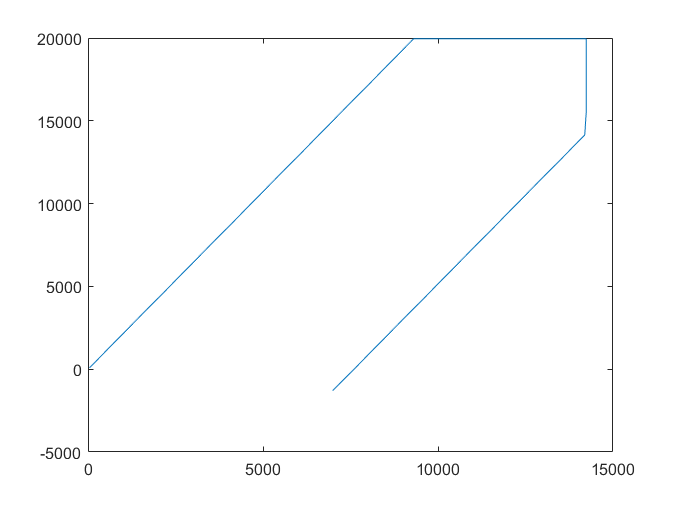

% cклеим все вместе 
X = horzcat(x1,x2,x3,x4);
Y = horzcat(y1,y2,y3,y4);
plot(X,Y)